%>>>>>>>>>>>>>>>>>> Matlab code for M ary-QAM modulation >>>>>>>>>>>>>>>>>%
clc;
clear all;
close all;
M=4;
%M=input(' enter the value of M array for QAM modulation : ');
fprintf('\n\n\n');
%XXXXXXXXXXXXXXXXXXXXXXXXXXX input  chaking loop XXXXXXXXXXXXXXXXXXXXXXXXXX
Ld=log2(M);
ds=ceil(Ld);
dif=ds-Ld;
if(dif~=0)
   error('the value of M is only acceptable if log2(M)is an integer');
end
%XXXXXXXXXXXXXXXXXXX binary Information Generation XXXXXXXXXXXXXXXXXXXXXXXX
nbit=16;                                        %number of information bits
msg=round(rand(nbit,1));            % information generation as binary form
disp(' binary information at transmitter ');

 binary information at transmitter 


disp(msg);

     1
     1
     0
     1
     1
     0
     0
     1
     1
     1
     0
     1
     1
     0
     1
     0



fprintf('\n\n');
%XX representation of transmitting binary information as digital signal XXX
x=msg;
bp=.000001;                                                    % bit period
bit=[]; 
for n=1:1:length(x)
    if x(n)==1;
       se=ones(1,100);
    else x(n)==0;
        se=zeros(1,100);
    end
     bit=[bit se];
end
t1=bp/100:bp/100:100*length(x)*(bp/100);
figure(1)
subplot(3,1,1);
plot(t1,bit,'lineWidth',2.5);grid on;
axis([ 0 bp*length(x) -.5 1.5]);
ylabel('amplitude(volt)');
xlabel(' time(sec)');
title('transmitting information as digital signal');
% binary information convert into symbolic form for M-array QAM modulation
M=M;                                             % order of QAM modulation
msg_reshape=reshape(msg,log2(M),nbit/log2(M))';
disp(' information are reshaped for convert symbolic form');

 information are reshaped for convert symbolic form


disp(msg_reshape);

     1     1
     0     1
     1     0
     0     1
     1     1
     0     1
     1     0
     1     0



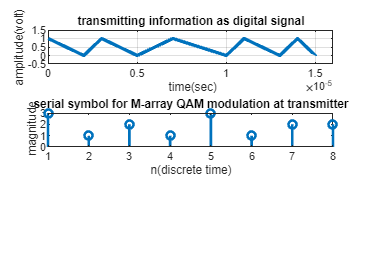

fprintf('\n\n');
size(msg_reshape);
for(j=1:1:nbit/log2(M))
   for(i=1:1:log2(M))
       a(j,i)=num2str(msg_reshape(j,i));
   end
end
as=bin2dec(a);
ass=as';
figure(1)
subplot(3,1,2);
stem(ass,'Linewidth',2.0);
title('serial symbol for M-array QAM modulation at transmitter');
xlabel('n(discrete time)');
ylabel(' magnitude');

disp('symbolic form information for M-array QAM ');

symbolic form information for M-array QAM 


disp(ass);

  Columns 1 through 5

     3     1     2     1     3

  Columns 6 through 8

     1     2     2



fprintf('\n\n');
%XXXXXXXXXXXXXX Mapping for M-array QAM modulation XXXXXXXXXXXXXXXXXXXXXXXX
M=M;                                               %order of QAM modulation
x1=[0:M-1];
p=qammod(ass,M)     %constalation design for M-array QAM acording to symbol

'qammod' requires Communications
Toolbox.

sym=0:1:M-1;     % considerable symbol of M-array QAM, just for scatterplot
pp=qammod(sym,M);                     %constalation diagram for M-array QAM         
scatterplot(pp),grid on;
title('consttelation diagram for M-array QAM');
%XXXXXXXXXXXXXXXXXXXXXX  M-array QAM modulation XXXXXXXXXXXXXXXXXXXXXXXXXXX
RR=real(p)
II=imag(p)
sp=bp*2;                                     %symbol period for M-array QAM
sr=1/sp;                                                      % symbol rate
f=sr*2;
t=sp/100:sp/100:sp;
ss=length(t);
m=[];
for(k=1:1:length(RR))
    yr=RR(k)*cos(2*pi*f*t);                     % inphase or real component
    yim=II(k)*sin(2*pi*f*t);            % Quadrature or imagenary component 
    y=yr+yim;
    m=[m y];
end
tt=sp/100:sp/100:sp*length(RR);
figure(1);
subplot(3,1,3);
plot(tt,m);
title('waveform for M-array QAM modulation acording to symbolic information');
xlabel('time(sec)');
ylabel('amplitude(volt)');
%XXXXXXXXXXXXXXXXXXXX M-array QAM demodulation XXXXXXXXXXXXXXXXXXXXXXXXXXXX
m1=[];
m2=[];
for n=ss:ss:length(m)
  t=sp/100:sp/100:sp;
  y1=cos(2*pi*f*t);                                     % inphase component
  y2=sin(2*pi*f*t);                                  % quadrature component
  mm1=y1.*m((n-(ss-1)):n);                                    
  mm2=y2.*m((n-(ss-1)):n);                                    
  z1=trapz(t,mm1)                                             % integration
  z2=trapz(t,mm2)                                             % integration
  zz1=round(2*z1/sp)
  zz2=round(2*z2/sp)
  m1=[m1 zz1]
  m2=[m2 zz2]
end
%XXXXXXXXXXXXXXXXXXX de-mapping for M-array QAM modulation XXXXXXXXXXXXXXXX
clear i;
clear j;
for (k=1:1:length(m1))  
gt(k)=m1(k)+j*m2(k);
end
gt
ax=qamdemod(gt,M);
figure(3);
subplot(2,1,1);
stem(ax,'linewidth',2);
title(' re-obtain symbol after M-array QAM demodulation ');
xlabel('n(discrete time)');
ylabel(' magnitude');
disp('re-obtain symbol after M-array QAM demodulation ');
disp(ax);
fprintf('\n\n');
bi_in=dec2bin(ax);
[row col]=size(bi_in);
p=1;
 for(i=1:1:row)
     for(j=1:1:col)
         re_bi_in(p)=str2num(bi_in(i,j));
         p=p+1;
     end
 end 
disp('re-obtain binary information after M-array QAM demodulation');
disp(re_bi_in')
fprintf('\n\n');
%XX representation of receiving binary information as digital signal XXXXXX
x=re_bi_in;
bp=.000001;                                                    % bit period
bit=[]; 
for n=1:1:length(x)
    if x(n)==1;
       se=ones(1,100);
    else x(n)==0;
        se=zeros(1,100);
    end
     bit=[bit se];
end
t1=bp/100:bp/100:100*length(x)*(bp/100);
figure(3)
subplot(2,1,2);
plot(t1,bit,'lineWidth',2.5);grid on;
axis([ 0 bp*length(x) -.5 1.5]);
ylabel('amplitude(volt)');
xlabel(' time(sec)');
title('receiving information as digital signal after M-array QAM demoduation');
%>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>> end of program <<<<<<<<<<<<<<<<<<<<<<<<<
